Tarea IVPSR con Matriz de Coeficiente

M = [3 -2; 2 -2];

f = @(t,yz) M*yz

f = function_handle with value:
    @(t,yz)M*yz

           
yz0=[1;-1];
[t,yz] = ivps(f,0,2,yz0,0.1,1)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


yz =     1.0000    1.5000    2.0700    2.7270    3.4911    4.3862    5.4405    6.6881    8.1692    9.9321   12.0348   14.5464   17.5498   21.1445   25.4496   30.6082   36.7915   44.2055   53.0966   63.7609   76.5536
   -1.0000   -0.6000   -0.1800    0.2700    0.7614    1.3073    1.9231    2.6266    3.4389    4.3849    5.4944    6.8025    8.3512   10.1909   12.3816   14.9952   18.1178   21.8526   26.3231   31.6778   38.0944


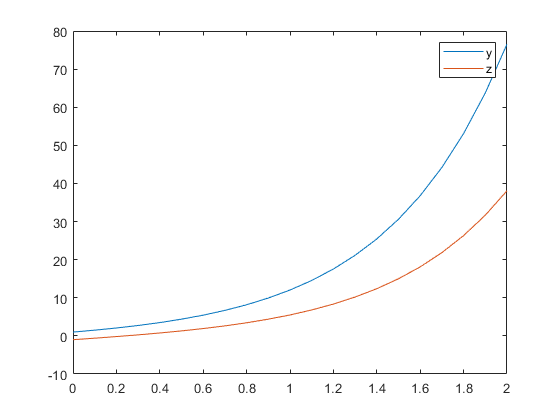

plot(t,yz)
legend('y','z');

[V,D]=eig(M)

V =     0.8944    0.4472
    0.4472    0.8944


D =      2     0
     0    -1



c = yz0\V

c =     0.2236   -0.2236
